# Analisi spettro di potenza

clear all
load Dati/sst_nino3_m.dat;
load Dati/time_nino3_m.dat;

## PERIODOGORAMMA

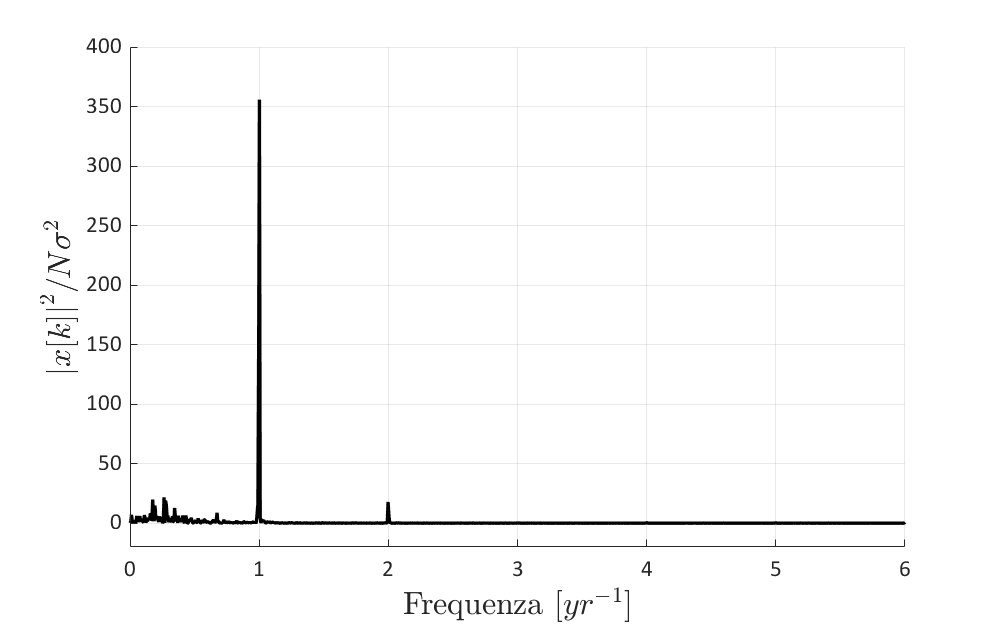

[nino_mean nino_sigma] = normfit(sst_nino3_m);
nino_serie = normalize(sst_nino3_m,'zscore');

nfft = 2048;
f_s = 12; % anni^(-1)

[Pxx, f] = periodogram(nino_serie, [], nfft, f_s, 'twosided'); % Le parentesi quadre indicano la finestra rettangolare
Pxx = Pxx*f_s; % Normalizzazione spettrale

[B,I] = maxk(Pxx(1:nfft/2+1),20);
B(2) = [];
I(2) = [];

f1 = figure;
f1.Position = [90 90 800 500];

plot(f(1:nfft/2+1), Pxx(1:nfft/2+1), 'color','k', 'LineWidth', 2, 'HandleVisibility','off')
hold on
set(gca,'box','off')
set(gca,'FontSize',14,'FontName','Calibri');
xlabel('Frequenza $[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('${|x[k]|}^2/N\sigma^2$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylim([-20 400])
% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.1;
hold off
print('Grafici/periodogram','-dpng')

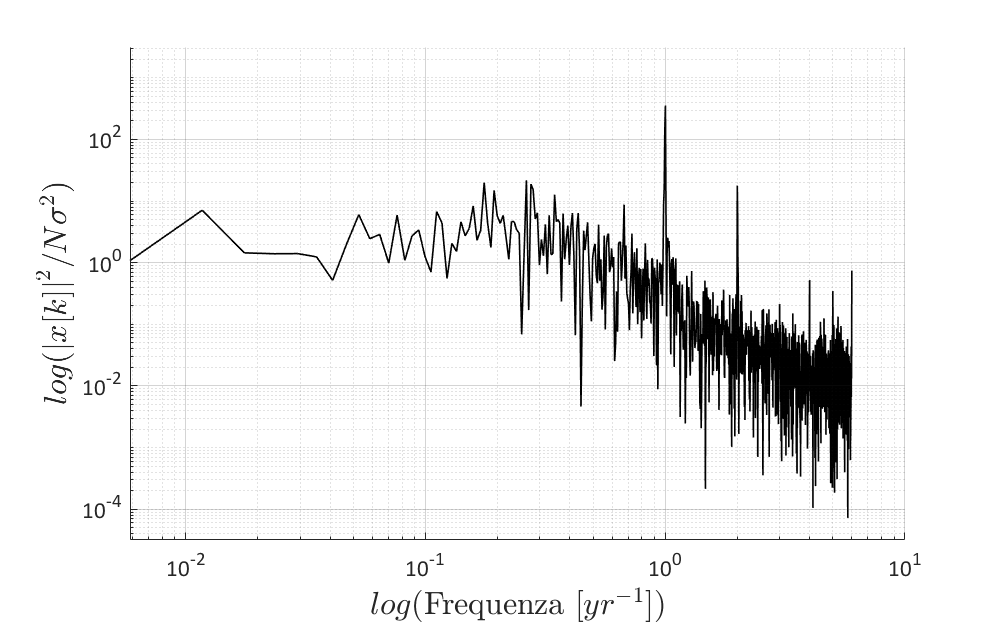


f2 = figure;
f2.Position = [90 90 800 500];
loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1)
hold on
set(gca,'FontSize',14,'FontName','Calibri');
xlabel('$log$(Frequenza $[yr^{-1}]$)', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log({|x[k]|}^2/N\sigma^2)$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off

set(gca,'box','off')


print('Grafici/periodogram_loglog','-dpng')

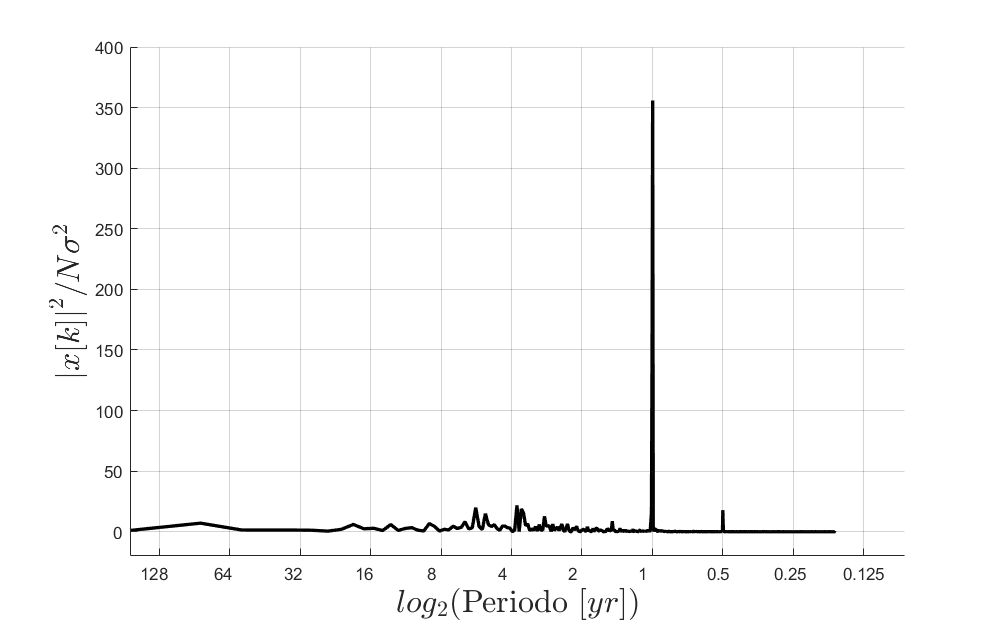

% Grafico lineare-log2
f3 = figure;
f3.Position = [90 90 800 500];

period = 1./f;
plot(log2(period(2:nfft/2+1)), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 2, 'HandleVisibility','off')
hold on

Xticks = 2.^( fix(log2(min(period(2:end)))):fix(log2(max(period(2:end)))) );
set(gca,'XDir','reverse');
set(gca,'Xlim',log2([min(period),max(period)]));
set(gca,'XTick',log2(Xticks(:)));
set(gca,'XTickLabel',Xticks);

xlabel('$log_2$(Periodo $[yr]$)', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('${|x[k]|}^2/N\sigma^2$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylim([-20 400])

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off

set(gca,'box','off')

print('Grafici/periodogram_log2lin','-dpng')

# Analisi spettro di potenza - Whitening

clear all
load Dati/a_sst_nino3_m.dat;
load Dati/time_nino3_m.dat;

sst_nino3_m = a_sst_nino3_m;

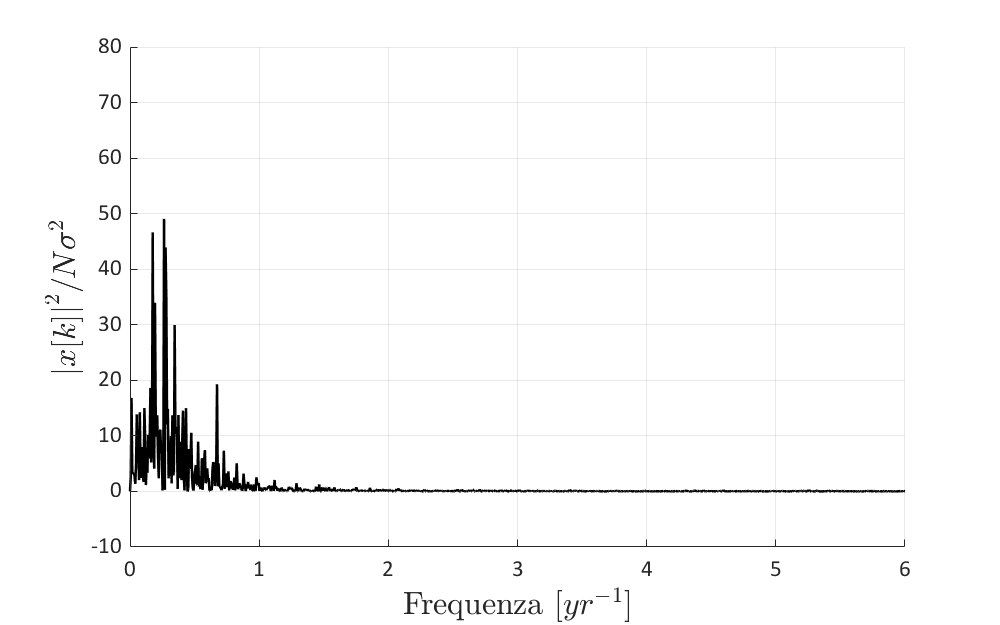

[nino_mean nino_sigma] = normfit(sst_nino3_m);
nino_serie = normalize(sst_nino3_m,'zscore');

nfft = 2048;
f_s = 12; % anni^(-1)

[Pxx, f] = periodogram(nino_serie, [], nfft, f_s, 'twosided'); % Le parentesi quadre indicano la finestra rettangolare
Pxx = Pxx*f_s; % Normalizzazione spettrale

[B,I] = maxk(Pxx(1:nfft/2+1),20);
B(2) = [];
I(2) = [];

% Grafico lineare, con frequenze sulla x
f4 = figure;
f4.Position = [90 90 800 500];

plot(f(1:nfft/2+1), Pxx(1:nfft/2+1), 'color','k', 'LineWidth', 1.5, 'HandleVisibility','off')
set(gca,'FontSize',14,'FontName','Calibri');
xlabel('Frequenza $[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('${|x[k]|}^2/N\sigma^2$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylim([-10 80])

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.1;
hold off

set(gca,'box','off')

print('Grafici/periodogram_wht','-dpng')

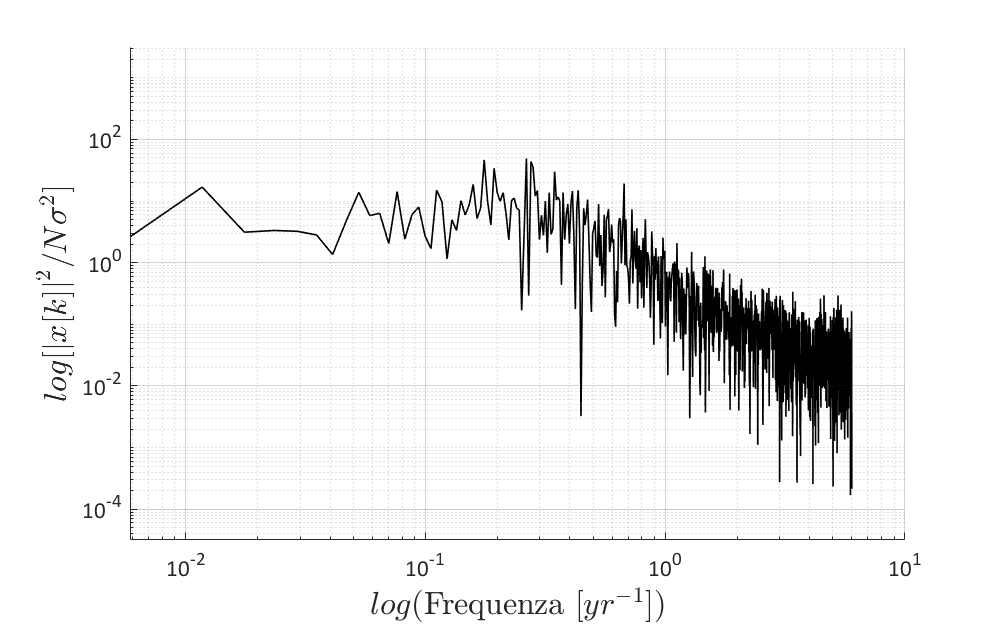


f5 = figure;
f5.Position = [90 90 800 500];

loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1)
set(gca,'FontSize',14,'FontName','Calibri');
xlabel('$log$(Frequenza $[yr^{-1}]$)', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off

set(gca,'box','off')


print('Grafici/periodogram_loglog_wht','-dpng')

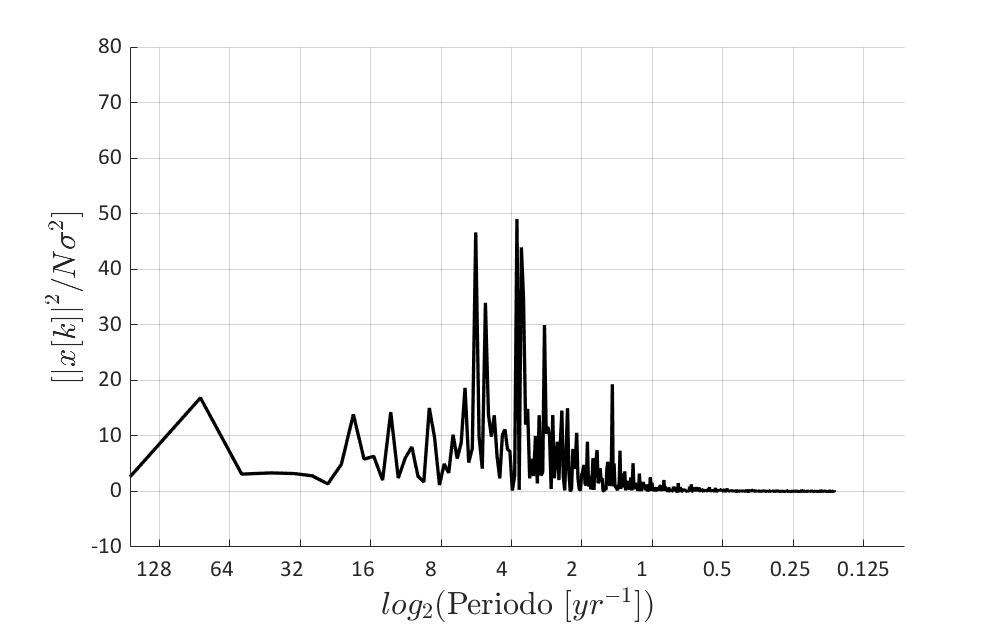

% Grafico lineare-log2
f6 = figure;
f6.Position = [90 90 800 500];

period = 1./f;
plot(log2(period(2:nfft/2+1)), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 2, 'HandleVisibility','off')
set(gca,'FontSize',14,'FontName','Calibri');

Xticks = 2.^( fix(log2(min(period(2:end)))):fix(log2(max(period(2:end)))) );
set(gca,'XDir','reverse');
set(gca,'Xlim',log2([min(period),max(period)]));
set(gca,'XTick',log2(Xticks(:)));
set(gca,'XTickLabel',Xticks);

xlabel('$log_2$(Periodo $[yr^{-1}]$)', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylim([-10 80])

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off

set(gca,'box','off')

print('Grafici/periodogram_log2lin_wht','-dpng')